# **Lab #1: Introduction to MATLAB**

**Problem 1.  MATLAB Onramp Tutorial.**

**Task 1. C**omplete the MATLAB Onramp Tutorial. **Be sure to upload your completion certificate to Gradescope.**

**In the following set of tasks, enter and execute your code in the "Code"   sections, and answer the  underlined questions in a "Text " section before or after your code section.**

**Problem 2: Deciphering an audio message**

This problem is about using array/matrix operations to  decipher an encrypted  audio message.

**Task 1. **Load the file `Lab_1_F23.mat`.  Verify that the variables X and Fs are added to your workspace.

load 'Lab_1_F23.mat'

**Task 2.** Determine the size of the array X.  Determine the value of Fs`.`

Is X a row vector or a column vector?   

display(length(X))

      124152



display(Fs);

Fs = 44100

The array X  is a complex-valued discrete-time signal  that represents an encrypted audio signal Y of length N. 

(You can try playing the real part, imaginary part, magnitude, and phase of X, and they won't sound like any useful message.)   

The encryption process was the following.

- Using a secret seed, a random reordering or permutation, `perm`, of the numbers from 1 to N was generated.

- The elements of the signal vector Y were then scrambled according to the permutation, creating a new signal Z=Y(perm).  

- A  complex vector W was created, with real part equal to the first $\frac{N}{2}$ elements of Z, and imaginary part equal to the last  $\frac{N}{2}$elements.     

- Finally, the vector X was created with real part equal to the magnitude of W, and imaginary part equal to the phase of W. 

**Task 3**. Decipher the  signal using array/matrix operations. Do not use loops. You can use the commands `real`, `imag`, `abs`, `angle`, and `exp`, as needed`. `

More specifically,  to decipher X, do the following:

- Determine from X the value of N.        <-- why this instruction??

- From the real and imaginary parts of X, recover the vector  W using Euler's formula.

- From the real and imaginary parts of W, recover  the vector Z using an array concatenation operation. 

- Recreate the permuation `perm,`setting the secret seed to 2023 with the command `rng(2023), `and` perm=randperm(N).`

- Finally, recover the signal Y.  What is the size of your recovered signal?

 mW = real(X);
 pW = imag(X);
 W = mW.*exp(1j*pW)

W =    0.0350 + 0.0233i
   0.1818 + 0.0440i
  -0.0183 + 0.0470i
   0.0396 - 0.0035i
   0.0241 - 0.0681i
  -0.0189 - 0.0148i
  -0.0558 - 0.1093i
   0.0135 + 0.0028i
   0.0037 - 0.0871i
   0.0392 + 0.0184i


 Z = [real(W); imag(W)]

Z =     0.0350
    0.1818
   -0.0183
    0.0396
    0.0241
   -0.0189
   -0.0558
    0.0135
    0.0037
    0.0392


 N = length(Z);
 
 rng(2023);
 perm = randperm(N);
 invPerm(perm) = 1:length(perm)

invPerm =        79615      221118      146005       31478       35116      116107        5550      180745      130280      135271      113234      124444       97630       37628       89310       40388       83543       44848       96737        8979      140207       50412       79279       93174       45704       25871      112844       48562       93640      231086      188894      191440      148171      196653      201266      243568      219713       27330      203614       75994       64587      100405      137339      155439       19587      241552      101816      179347      164888       53939


Z_flat = Z(:); % Flatten Z into a 1D array
Y = Z_flat(invPerm)

Y =     0.0000
         0
         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
         0


sizeY = length(Y)

sizeY = 248304

**Task 4. **Play the sound file Y. using playback rate F`s`. 

Can you recognize the language being spoken?

 %sound(Y, Fs)
 %no

**Task 5.  **Create an array M that is the flipped version of Y. You will have to decide which flip command to  use, ` fliplr`  or `flipud`.  

Now play the sound file M. 

`Write the words that you hear.`

Do you know the origin of this audio clip? 

M = flipud(Y);
sound(M, Fs); 

**Task 6.**  Plot both signals Y and M`. `

Label the $x$-axis 'Time (seconds)', with numerical scale and tick marks on the $x$-axis corresponding to actual time (in seconds). 

Label the $y$-axis 'Amplitude'.  For both plots, use the title command to write the message contents over the plot. 

(You should use two lines for each of the titles.)

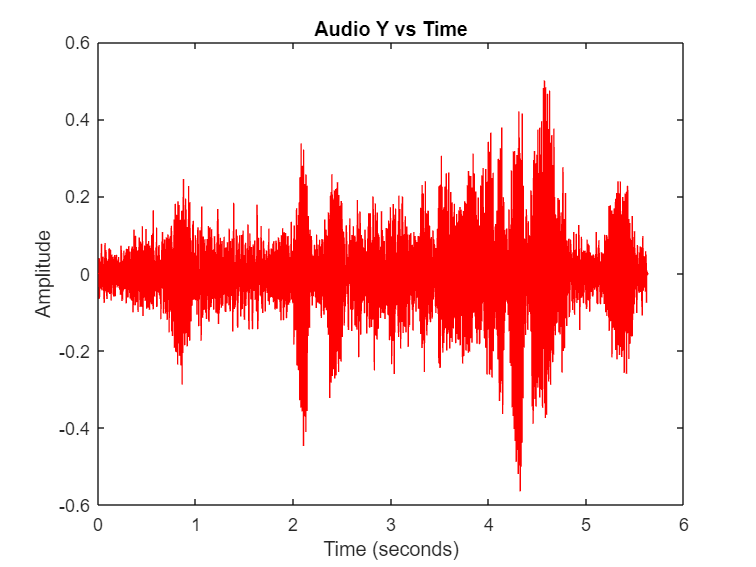

t = (0:sizeY -1)/Fs;
figure;
plot(t, Y, 'r');
xlabel("Time (seconds)");
ylabel("Amplitude");
title("Audio Y vs Time");

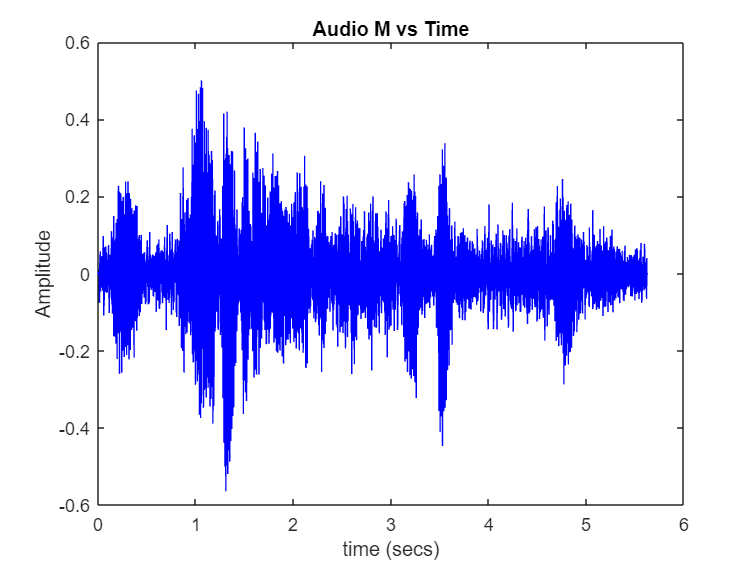


figure;
plot(t, M, "b");
xlabel('time (secs)');
ylabel("Amplitude");
title("Audio M vs Time");

**Task 7. **Play M again, with a playback rate of F`s/2`. 

How has the character of the sound changed?

 %sound(M, Fs/2)

**Task 8. **Play it once more, now with a playback rate of 2`*Fs`. 

What does this do to the character of the sound?

%sound(M, Fs*2)

**Problem 3: Operations on vectors**

**Task 1: **Write a MATLAB function 'decimate' that removes every other element from an arbitrary length vector, creating a shorter vector made up of only the elements with odd index numbers in the original vector.  

**Use only matrix/vector manipulations; do NOT use loops.**

Write your function in a code box here but with all lines commented out. You will have to write the actual function in a code box at the very end of your LiveScript for it to be called properly.


%function decimate(inputVector)
% outputVector = inputVector(1:2:end);
%end

**Task 2. **Write a MATLAB function 'interpolate' that creates a longer vector by adding an additional element between neighboring elements in the original vector.

Each new element should equal the average of its neighboring elements. 

**Again, use only matrix/vector manipulations; do NOT use loops.**

Again, write your function in a  code box here but with all lines commented out. Write the actual function in the same code box used for the function in Task 1 at the very end of your LiveScript.

% function interpolate(inputVector)

% function outputVector = interpolate(inputVector)
% shiftVector = inputVector(2:end);

% interpolatedValues = (inputVector(1:end-1) + shiftVector) / 2;

% outputVector = reshape([inputVector(1:end-1); interpolatedValues], 1, []);
% outputVector = [outputVector, inputVector(end)];

% end


**Task 3.**

Test your solution by applying 'decimate' and then 'interpolate' to the vector   `x= [7 6 5 4 3 2 1 2 3 4 5 6 7]`. 

Then apply them to the vector `y=[8 7 6 5 4 3 2 1 2 3 4 5 6 7 8]`.

Now apply the two operations in succession, in both orders, to each of x and y. 

What happens after the execution of 'decimate' followed by 'interpolate', and 'interpolate' followed by 'decimate'? 

Does the order of operation affect the result? 

Under what general conditions do these two functions commute? 

Considering integer "V" signals like x and y, for which lengths  will the operations commute?

x= [7 6 5 4 3 2 1 2 3 4 5 6 7]

x =      7     6     5     4     3     2     1     2     3     4     5     6     7


decx = decimate(x)

decx =      7     5     3     1     3     5     7


interx = interpolate(x)

interx =     7.0000    6.5000    6.0000    5.5000    5.0000    4.5000    4.0000    3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000


y=[8 7 6 5 4 3 2 1 2 3 4 5 6 7 8]

y =      8     7     6     5     4     3     2     1     2     3     4     5     6     7     8


decy = decimate(y)

decy =      8     6     4     2     2     4     6     8


intery = interpolate(y)

intery =     8.0000    7.5000    7.0000    6.5000    6.0000    5.5000    5.0000    4.5000    4.0000    3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000


x = decimate(x)

x =      7     5     3     1     3     5     7


x = interpolate(x)

x =      7     6     5     4     3     2     1     2     3     4     5     6     7


x = interpolate(x)

x =     7.0000    6.5000    6.0000    5.5000    5.0000    4.5000    4.0000    3.5000    3.0000    2.5000    2.0000    1.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000


x = decimate(x)

x =      7     6     5     4     3     2     1     2     3     4     5     6     7


y = decimate(y)

y =      8     6     4     2     2     4     6     8


y = interpolate(y)

y =      8     7     6     5     4     3     2     2     2     3     4     5     6     7     8


y= interpolate(y)

y =     8.0000    7.5000    7.0000    6.5000    6.0000    5.5000    5.0000    4.5000    4.0000    3.5000    3.0000    2.5000    2.0000    2.0000    2.0000    2.0000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000


y = decimate(y)

y =      8     7     6     5     4     3     2     2     2     3     4     5     6     7     8



%decimate halves(+1) the size while interpolate doubles(-1)
%the order of operation affects the result by changing the values that go
%into the next function.
% the interpolate function preserve original values so can uphold the same
% values if interpolate then decimate but the operations commute only if
% the signal is structured so that interpolation perfectly reconstructs 
% missing values


**Task 4. **Separately apply the functions `decimate` and `interpolate` to the sound vector `M` (reshaped, as necessary) that you created in Problem 1. 

Play the resulting vectors with playback rate of Fs. 

How would you characterize the audible effects of applying the two operations?

How do they compare with the results in Problem 2 from using playback at half and twice the nominal rate of Fs? 

Do you think the corresponding reconstructed audio signals in Problem 2 and Problem 3 are truly identical? Explain your reasoning. 

(**Note:** you are not expected to answer the last question rigorously at this stage. Once we study sampling theory, you will be able to.) 

**Problem 4. Complex functions**

**Task 1.** Refer to the 5-leaf rose function in Problem 3 of the Lecture 1 Demo. 

Give a mathematical formula for a complex function $z(\theta)=r(\theta)e^{j\theta}$ whose plot in the complex plane is an 8-leaf rose.  

Now, set n = 0:199, then multiply n by (2π/200) to get a vector θ containing 200 values from 0 to 2π. Implement and plot your function your function z(θ) in the complex 

n = 0:199;                     
theta = (2*pi/200) * n    

theta =          0    0.0314    0.0628    0.0942    0.1257    0.1571    0.1885    0.2199    0.2513    0.2827    0.3142    0.3456    0.3770    0.4084    0.4398    0.4712    0.5027    0.5341    0.5655    0.5969    0.6283    0.6597    0.6912    0.7226    0.7540    0.7854    0.8168    0.8482    0.8796    0.9111    0.9425    0.9739    1.0053    1.0367    1.0681    1.0996    1.1310    1.1624    1.1938    1.2252    1.2566    1.2881    1.3195    1.3509    1.3823    1.4137    1.4451    1.4765    1.5080    1.5394


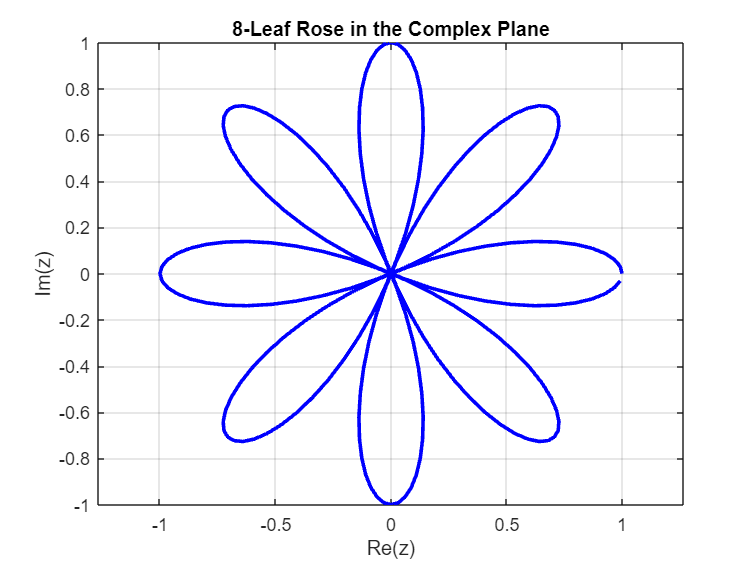



z = exp(1i * theta) .* cos(4 * theta);

% Plot
figure
plot(real(z), imag(z), 'b', 'LineWidth', 2)
axis equal;
xlabel('Re(z)');
ylabel('Im(z)');
title('8-Leaf Rose in the Complex Plane');
grid on;

Using the technique of Problem 3 of the Lecture 1 Demo, plot the points one at a time, as $\theta$ ranges over the 200 values from $0$ to $2\pi$.  If you number the petals from 1 through 8 in the clockwise direction, starting from the top right, what order do the petals get traced out as $\theta$ ranges from $0$ to $2\pi$. 

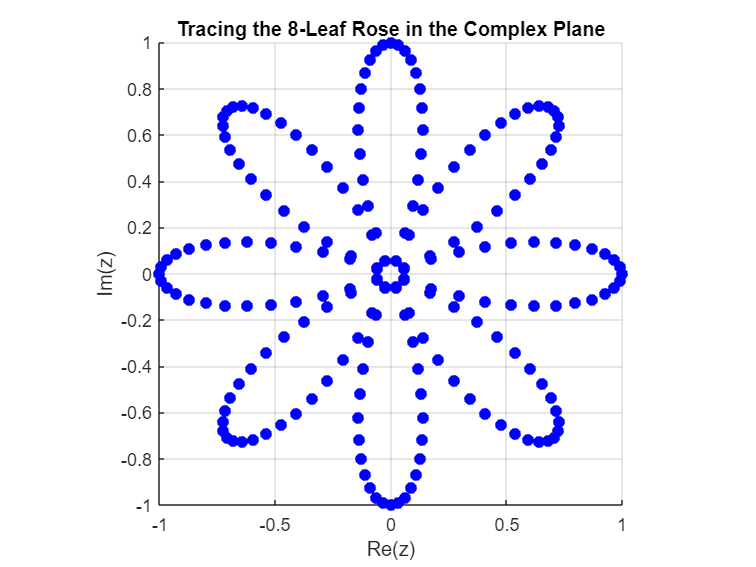

%same equation
n = 0:199;                     
theta = (2*pi/200) * n;    
z = exp(1i * theta) .* cos(4 * theta);

% Init
figure;
hold on;
axis equal;
xlabel('Re(z)');
ylabel('Im(z)');
title('Tracing the 8-Leaf Rose in the Complex Plane');
grid on;


xlim([-1, 1]);
ylim([-1, 1]);

% Animate the points one at a time
for k = 1:length(z)
    plot(real(z(k)), imag(z(k)), 'bo', 'MarkerFaceColor', 'b');
    pause(0.05);  % Pause for animation
end
hold off;

**Task 2.** Determine mathematically the formulas for the real and imaginary parts of $z(\theta)$,  expressing them as sums of sines and cosines.

**Task 3.  **In fact, when $r(\theta)=\sin(k\theta)$, the function  $z(\theta)=r(\theta)e^{j\theta},  0\leq \theta<2\pi$, creates a rose with $k$ petals when $k$ is odd, and a rose with $2k$ petals when $k$ is even.  So, how can we create a rose with 6 petals?  Try setting $k=3/2$. Can you trace out the whole rose by letting $\theta$ run from $0$ to $2\pi$? How about if you let $\theta$ run from $0$ to $4\pi$? Use the technique of the Lecture 1 Demo to determine the order in which the petals are traced out, numbering them from 1 to 6, starting at the upper right. 

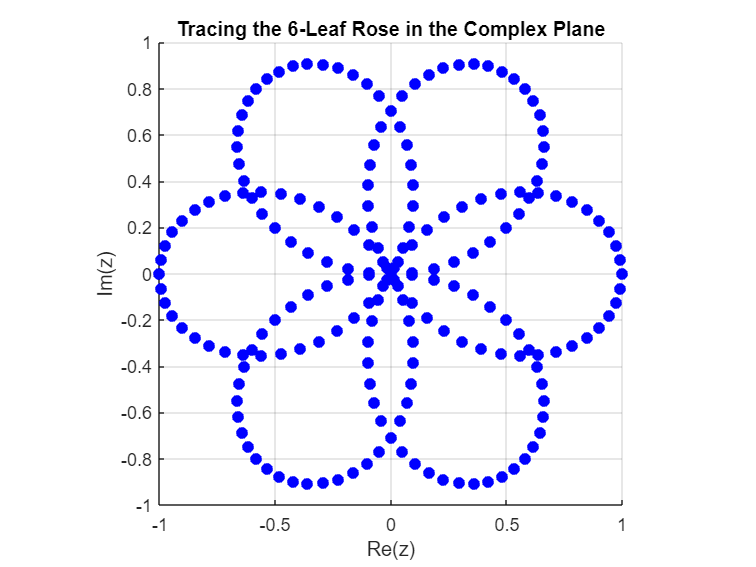


n = 0:199;                     
theta = (4*pi/200) * n;    

%z = exp(1i * theta) .* cos(3 * theta); 
z = exp(1i * theta) .* sin(3/2 * theta);
%z = exp(1i * theta) .* cos(3/2 * theta); 
% Initialize figure
figure;
hold on;
axis equal;
xlabel('Re(z)');
ylabel('Im(z)');
title('Tracing the 6-Leaf Rose in the Complex Plane');
grid on;

xlim([-1, 1]);
ylim([-1, 1]);

% Animate the points one at a time
for k = 1:length(z)
    plot(real(z(k)), imag(z(k)), 'bo', 'MarkerFaceColor', 'b');
    pause(0.05);  % Pause for animation
end
hold off;

Put your functions `decimate` and `interpolate` in the code block after the following dummy code block

0;

function outputVector = decimate(inputVector)
 outputVector = inputVector(1:2:end);
end


function outputVector = interpolate(inputVector)
 shiftVector = inputVector(2:end);

 interpolatedValues = (inputVector(1:end-1) + shiftVector) / 2;

 outputVector = reshape([inputVector(1:end-1); interpolatedValues], 1, []);
 outputVector = [outputVector, inputVector(end)];

end